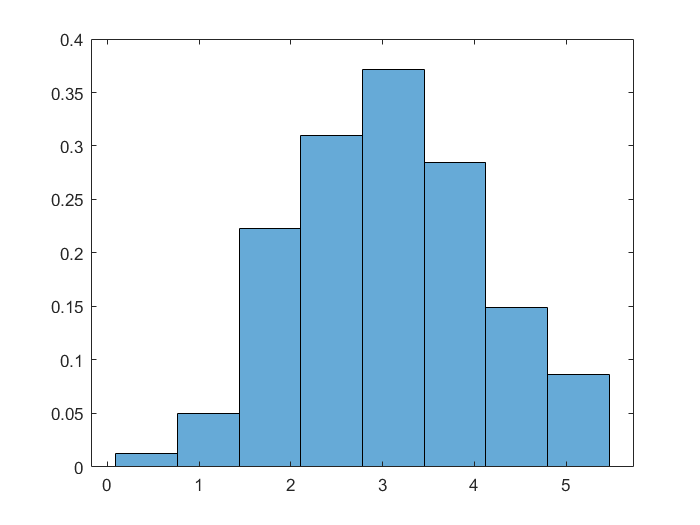

close all;


variationalSeries = sort(csvread('C:\Users\maria\OneDrive\Рабочий стол\МатСтат\Lab1\selection.csv'));
Mmin = variationalSeries(1);
Mmax = variationalSeries(length(variationalSeries));
R = Mmax - Mmin;
mu = NthSelectiveStartingTorque(variationalSeries, 1);
s2 = NthSelectiveAvgTorque(variationalSeries, 2);
m = floor(log2(length(variationalSeries))) + 2;
s = sqrt(s2);

m = floor(log2(length(variationalSeries))) + 2;
delta = R / m;

edges = Mmin : delta : Mmax;
for_histogram = histogram(variationalSeries, edges, 'normalization', 'pdf');

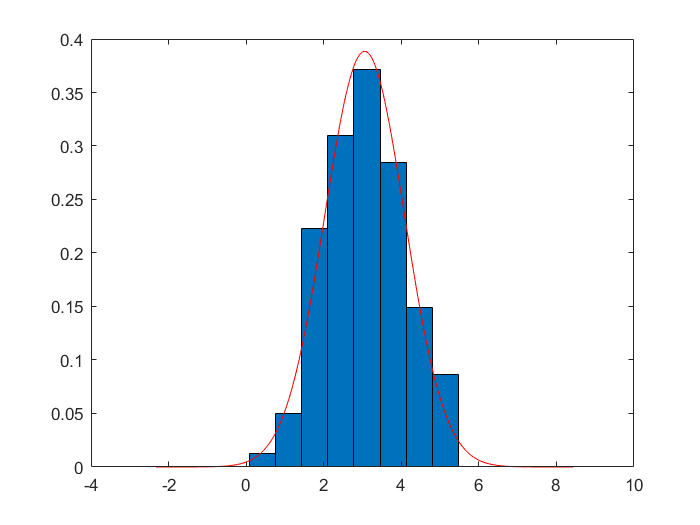


edge_center = zeros(length(for_histogram.Values), 1);
for i = 1 : length(edge_center)
    edge_center(i) = (edges(i) + delta / 2);
end

x_n = (mu - R) : delta / 100 :(mu + R);

y_plotn = normpdf(x_n, mu, s); 
figure
bar(edge_center, for_histogram.Values, 1);
hold on;
plot(x_n, y_plotn, 'r');
hold off;

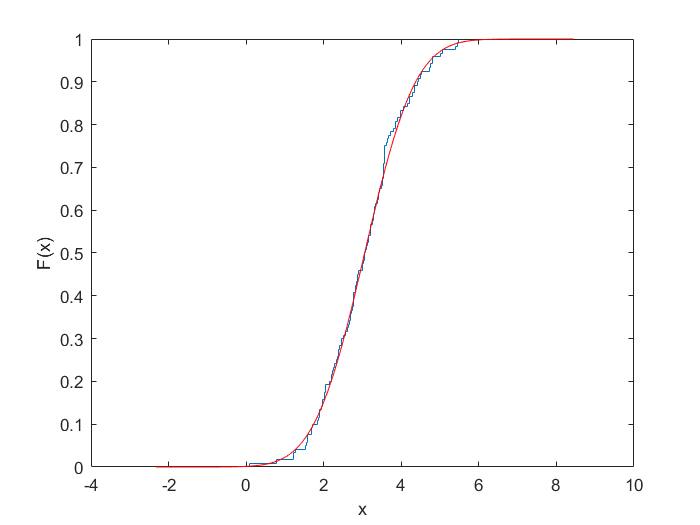


y_normal = normcdf(x_n, mu, s);
figure
ecdf(variationalSeries);
hold on;
plot(x_n, y_normal, 'r');
hold off;

function y = NthSelectiveStartingTorque(x, n)
sum = 0;
len = length(x);
for i = 1:len
    sum = sum + x(i)^n;    
end
y = sum/len; 
end

function k = NthSelectiveAvgTorque(x, n)
mu1 = NthSelectiveStartingTorque(x, 1); 
sum = 0;
len = length(x);
for i = 1:len
    sum = sum + (x(i) - mu1)^n;    
end
k = sum/(len - 1); 
end



